# Faces Project

[[Data Description](https://ocw.mit.edu/courses/sloan-school-of-management/15-097-prediction-machine-learning-and-statistics-spring-2012/datasets/housing_info.txt)] [[Data Set](https://ocw.mit.edu/courses/sloan-school-of-management/15-097-prediction-machine-learning-and-statistics-spring-2012/datasets/housing.txt)] [[Google Doc](https://docs.google.com/document/d/1iSObw7VH5_WYRtUrYXdGjfHjyoe7SsCMkDx0-AOV9Q0/edit)]

**Chosen context**: housing in Greater Boston, differences in appraised value based on assumed race of surrounding property owner(s)

**Big question**: To what extent would race impact the appraised value of a property?

**Sub-question(s)**:

- Which parameters have the biggest impact on the appraisal of a house in Greater Boston?

- What is the difference between appraised values of houses between a machine that takes race into account as opposed to one that does not?

**Analysis**: PCA, SVD, NN classification, linear regression

**Results**: one algorithm trained on two different data sets (one with race, one without); plot accuracy of algorithms against the actual data; plot difference between the two algorithms’ appraisals on the test data depending on race awareness

housingB = load('housing.txt');

% The housingBTrain and housingBTest include all columns from dataset with
% the exception of column 4, which is a dummy variable. The housingNoB
% training and testing tables are race blind, so they do not take into
% account the proportions of black people and

housingBTrain = [housingB(1:253, 1:3) housingB(1:253, 5:14)];
housingNoBTrain = [housingB(1:253, 1:3) housingB(1:253, 5:11) housingB(1:253, 14)];
housingBTest = [housingB(254:end, 1:3) housingB(1:253, 5:14)];
housingNoBTest = [housingB(254:506, 1:3) housingB(1:253, 5:11) housingB(254:506, 14)];

[NN] = eigenappraiser(housingBTest, housingBTrain);
values = zeros(size(NN));

for i = 1:size(NN)
    values(i, 1) = housingBTrain(NN(i,1), 13);
end

accuracy = mean(values - housingBTest(:, 13))   % $1000s

accuracy = -0.3814

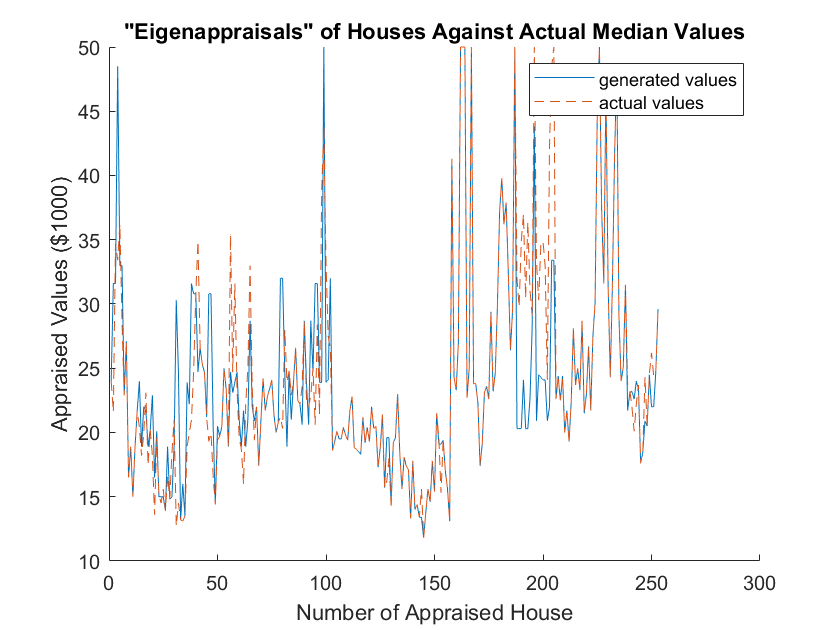


numRows = [1:253]';

clf; hold on;
plot(numRows, values); label1 = 'generated values';
plot(numRows, housingBTest(:, 13), "--"); label2 = 'actual values';
title('"Eigenappraisals" of Houses Against Actual Median Values');
xlabel('Number of Appraised House');
ylabel('Appraised Values ($1000)');
legend({label1, label2});

% No racial data included
[NNNoB] = eigenappraiser(housingNoBTest, housingNoBTrain);
valuesNoB = zeros(size(NNNoB));

for i = 1:size(NNNoB)
    valuesNoB(i, 1) = housingNoBTrain(NN(i,1), 11);
end

accuracyNoB = mean(valuesNoB - housingNoBTest(:, 11)) % $1000s

accuracyNoB = 3.1680

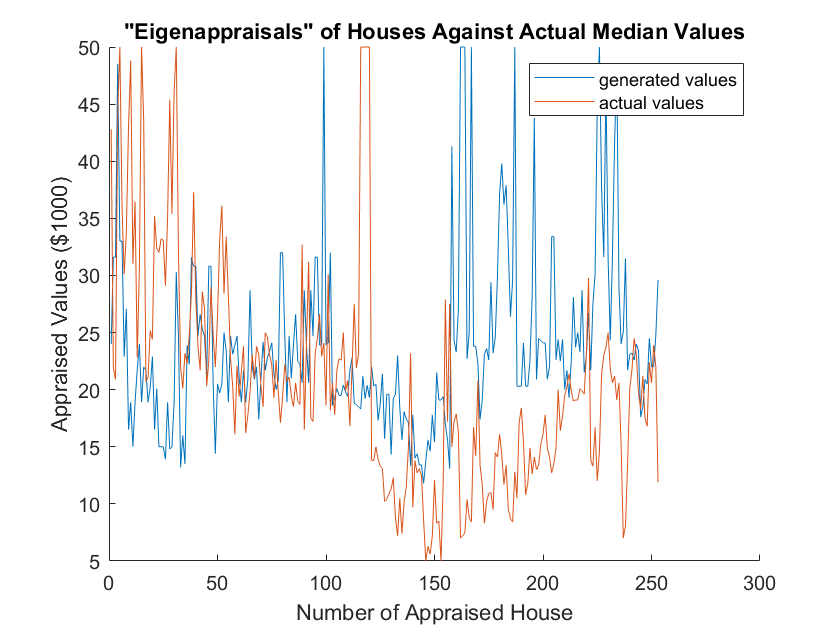

numRows = [1:253]';

clf; hold on;
plot(numRows, valuesNoB); label1 = 'generated values';
plot(numRows, housingNoBTest(:, 11)); label2 = 'actual values';
title('"Eigenappraisals" of Houses Against Actual Median Values');
xlabel('Number of Appraised House');
ylabel('Appraised Values ($1000)');
legend({label1, label2});

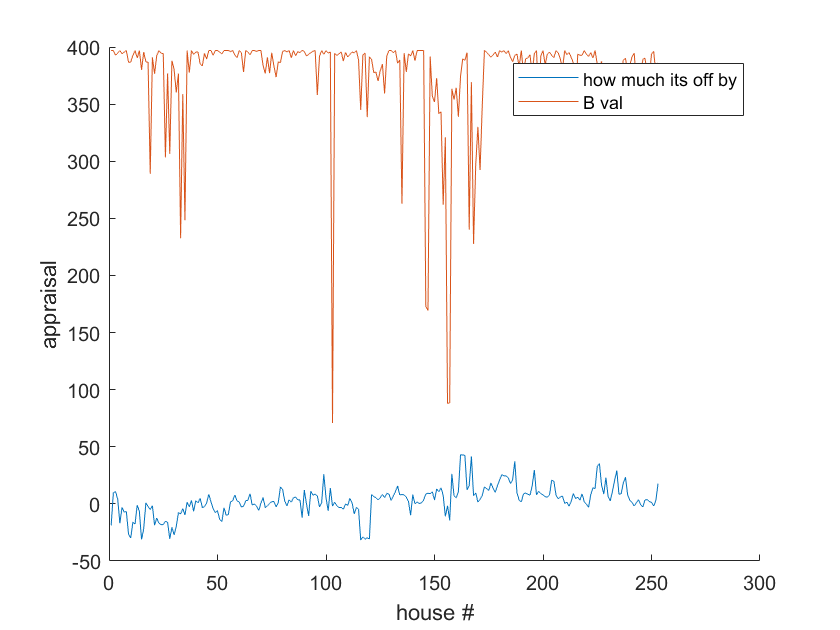

clf; hold on;
plot(numRows, valuesNoB - housingNoBTest(:, 11)); label1 = 'how much its off by';
plot(numRows, housingBTest(:, 11)); label2 = 'B val';
xlabel('house #'); ylabel('appraisal'); legend({label1, label2});

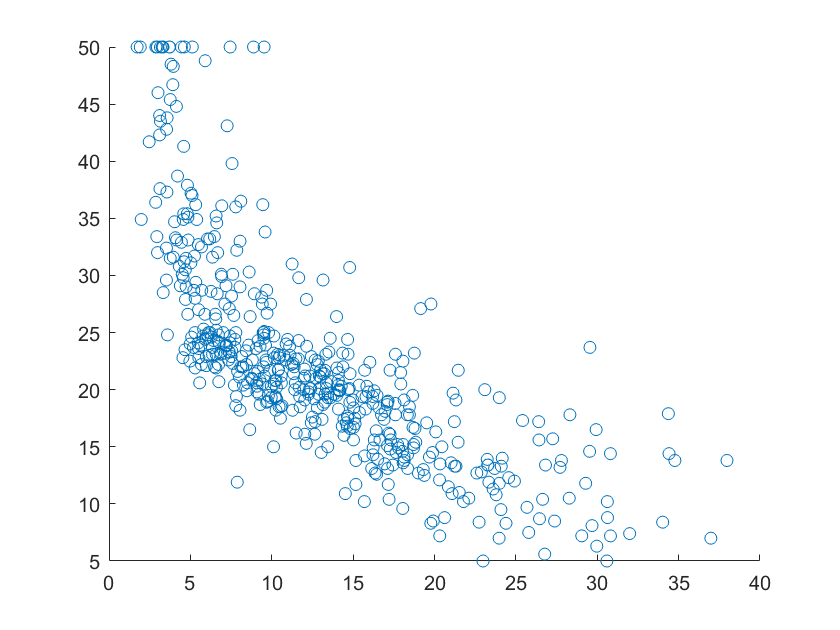


clf; hold on;
scatter(housingB(:,13), housingB(:,14));

((at the end)) include some discussion about how race is an implicit factor in many more parameters than just B and how we recognize that